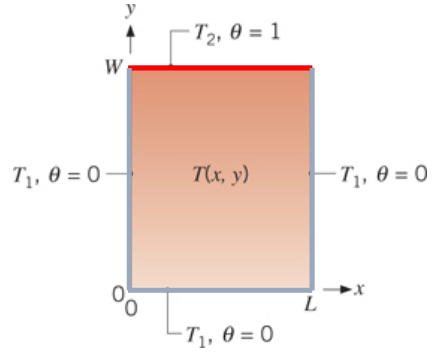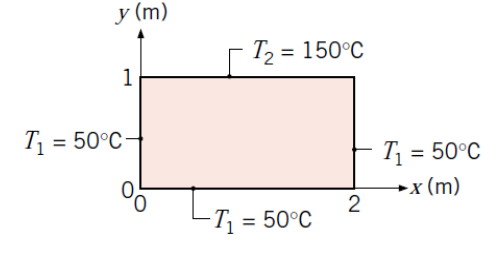

syms theta(x,y) x y T(x,y) 
T2 = 150 + 273.15;
T1 = 50 + 273.15;
n_end = 30;
W = 2;
L = 1;
sums = 0;

for n = 1:n_end
    sum_n = ((-1)^(n+1) + 1) / n * sin(n * pi * x / L * sinh(n*pi*y/L) / sinh(n*pi*W/L));
    sums = sums + sum_n;
end

theta(x,y) = 2/pi * sums

T(x,y) = T2 - T1*theta(x,y) + T2*theta(x,y)

% eq = theta1 == (Ttest - T2)/(T2-T1);
% Ttest = solve(eq, Ttest)

scalar_field = [];
x_lin = linspace(0,L,100);
y_lin = linspace(0,W,100);
for i = 1:100
    for j = 1:100
        scalar_field(i,j) = T(x_lin(i),y_lin(j));
    end
end

scalar_field

